## Run Simulation

Click **Run** to create an  `autoblks.pwr.PlantInfo` object that analyzes the model energy consumption. Use the `PwrUnits` and `EnrgyUnits` properties to set the units.

After you run the simulation, the live script provides the energy summary.  You can use the results to analyze energy and power losses at the component and system level. For more information, see [Explore the Hybrid Electric Vehicle Multimode Reference Application](matlab:helpview([docroot,'/toolbox/autoblks/helptargets.map'],'hybrid_refapp')).

SysName = 'HevMmReferenceApplication';
VehPwrAnalysis = autoblks.pwr.PlantInfo(SysName);
VehPwrAnalysis.PwrUnits = 'kW';
VehPwrAnalysis.EnrgyUnits = 'MJ';

Use `run` method to turn on logging, run simulation, and add logged data to the object.

VehPwrAnalysis.run;

### Starting serial model reference simulation build
### Model reference simulation target for SiEngineController is up to date.
### Model reference simulation target for HevMmPowertrainController is up to date.


## Overall Summary

Display the final energy values for each subsystem.

VehPwrAnalysis.dispSysSummary

               System Name                 Efficiency    Energy Loss (MJ)    Energy Input (MJ)    Energy Output (MJ)    Energy Stored (MJ)  
--------------------------------------------------------------------------------------------------------------------------------------------
HevMmReferenceApplication                       0.155               -54.7                   57                     0                   2.4  
  Passenger Car                                 0.155               -54.7                   57                     0                   2.4  
    Drivetrain                                  0.701               -10.7                 31.4                   -17                   3.7  


Write summary to spreadsheet.

VehPwrAnalysis.xlsSysSummary(fullfile(fileparts(which('GenerateEnergyReport')), 'EnergySummary.xlsx'))

## Engine Plant Summary

EngSysName = 'HevMmReferenceApplication/Passenger Car/Engine';
EngPwrAnalysis = VehPwrAnalysis.findChildSys(EngSysName);
EngPwrAnalysis.dispSignalSummary;

 
HevMmReferenceApplication/Passenger Car/Engine
Average Efficiency = 0.27
 
                  Signal                    Energy (MJ)  
---------------------------------------------------------
Inputs                                             56.9  
  Transferred                                         0  
    Accessory Load Model: Engine output               0  
  Not transferred                                  56.9  
Outputs                                           -15.6  
  Accessory Load Model: Engine output             -15.6  
Losses                                            -41.3  
Stored                                                0  


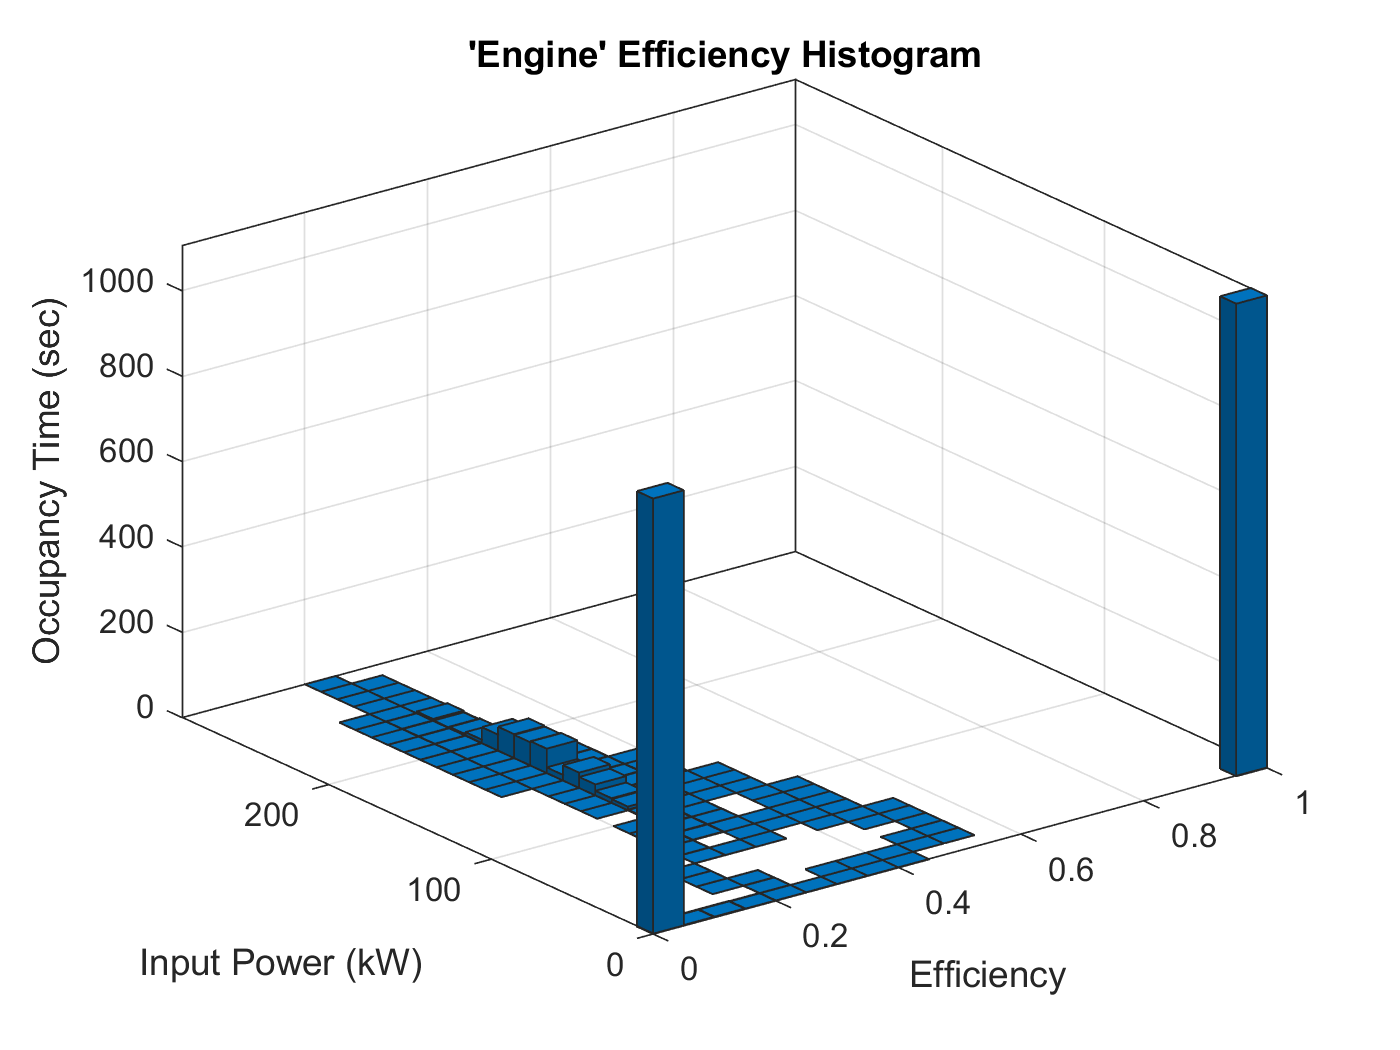

EngPwrAnalysis.histogramEff;

## Electric Plant Summary

ElecSysName = 'HevMmReferenceApplication/Passenger Car/Electric Plant';
ElecPwrAnalysis = VehPwrAnalysis.findChildSys(ElecSysName);
ElecPwrAnalysis.dispSignalSummary;

 
HevMmReferenceApplication/Passenger Car/Electric Plant
Average Efficiency = 0.91
 
           Signal             Energy (MJ)  
-------------------------------------------
Inputs                                 17  
  Transferred                          17  
    Generator: Motor shaft           15.4  
    Motor: Motor shaft               1.58  
  Not transferred                       0  
Outputs                             -15.7  
  Generator: Motor shaft                0  
  Motor: Motor shaft                -15.7  
Losses                              -2.65  
Stored                               -1.3  


## Drivetrain Plant Summary

DrvtrnSysName = 'HevMmReferenceApplication/Passenger Car/Drivetrain';
DrvtrnPwrAnalysis = VehPwrAnalysis.findChildSys(DrvtrnSysName);
DrvtrnPwrAnalysis.dispSignalSummary;

 
HevMmReferenceApplication/Passenger Car/Drivetrain
Average Efficiency = 0.70
 
                    Signal                      Energy (MJ)  
-------------------------------------------------------------
Inputs                                                 31.4  
  Transferred                                          31.3  
    Transmission Input Interface: Engine               15.6  
    Transmission Input Interface: Generator               0  
    Transmission Output Interface: Motor               15.7  
  Not transferred                                     0.102  
Outputs                                                 -17  
  Transmission Input Interface: Engine                    0  
  Transmission Input Interface: Generator             -15.4  
  Transmission Output Interface: Motor                -1.56  
Losses                                                -10.7  
Stored          

## SDI Plots

VehPwrAnalysis.sdiSummary({EngSysName, ElecSysName, DrvtrnSysName})